## Read in the oxy data

These people measured blood transmittance directly.  We used their graph, qualitatively, to select to blood optical density. It was impossible to see their numbers in detail, so we just picked a value that was approximately the right level, but we used the numerical data about oxy blood that was measured and shared in the literature.

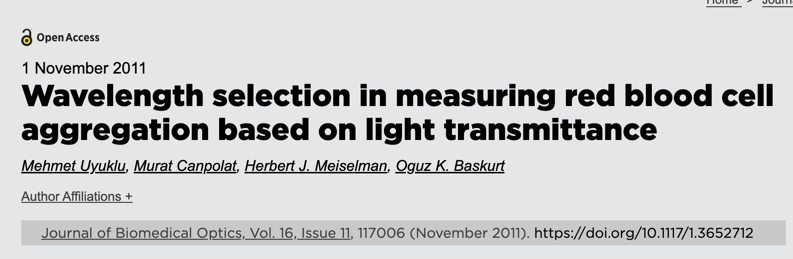

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

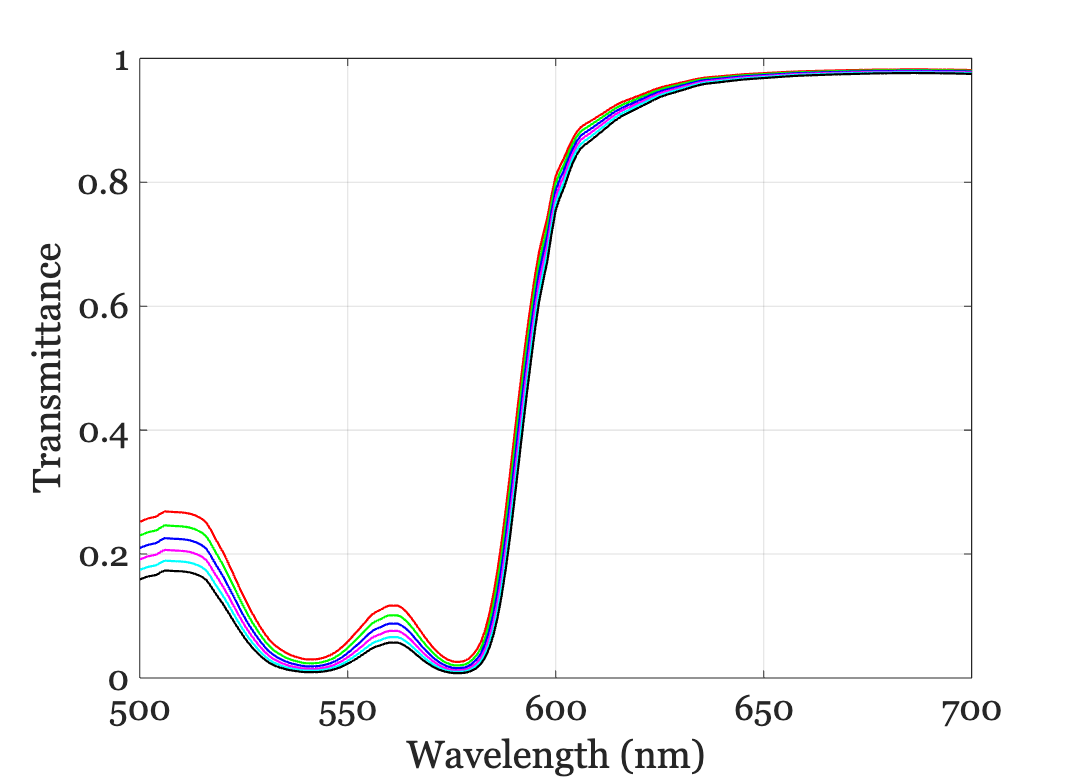

% {
ieFigure;
for od = (15:1:20)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');


%{
% From the literature
bloodTransmittance = ieReadSpectra('bloodT1.mat',wave);
plot(wave,bloodTransmittance/50,'k-','LineWidth',3);
%}